%% 小波变换+二次谐波心跳重构
%% ========================================================================
clc;
clear all;
close all;

%% =========================================================================
%% 参数设置
n_adc_samples = 256; % number of ADC samples per chirp
n_rx = 1;           % number of receivers
chirpLoop = 16;
Periodicity=10e-3; %帧周期
Fs=5e6;             %ADC采样率 
c=3*1e8;            %光速
ts=n_adc_samples/Fs;%ADC采样时间
k=66.626e12;        %调频斜率 
% B_valid =ts*slope;  %有效带宽
% B =3997.56e9;  %有效带宽  ??
% detaR=c/(2*B);%距离分辨率
fs=1/Periodicity;


%100Hz 10ms-1024\3\filled_data_3
%10ms-1024\withreal1\data_3

%% 读取Bin文件
fname = ['G:\CODE\FYP_matlab\FMCWradar\Rawdata\10ms-1024\withreal\data_3', '.bin'];
fid = fopen(fname,'r');
RawData = fread(fid, 'int16');
fclose(fid);

fileSize = size(RawData, 1);
%计算chirps数：数据量/天线数/采样点数/2(实部和虚部各占一个数据)。
n_chirps= fileSize/2/n_adc_samples/n_rx;
%读取所有ComplexData数据并写入数组ComplexData，总维数为：数据量/2(实部和虚部各占一个数据)。
ComplexData = zeros(1, fileSize/2);
counter = 1;
%数据格式：I1、I2、Q1、Q2依次排序。
for i = 1:4:fileSize-3
    %每4个数据的第1、3组成第一个采样点数据(复数)。
    ComplexData(1, counter) = RawData(i) + 1i*RawData(i+2);
    %每4个数据的第2、4组成第二个采样点数据(复数)。
    ComplexData(1, counter+1) = RawData(i+1) + 1i*RawData(i+3);
    %每4个数据含两个采样点数据，每次+2。
    counter = counter + 2;
end

%将数组ComplexData转换成矩阵Chirp_Division，每行数据为1个chirp的数据(含4个天线)，行高为总chirp数。
Chirp_Division = reshape(ComplexData, n_adc_samples*n_rx, n_chirps);
%转置。
Chirp_Division = Chirp_Division.';

%定义Rx_Division为“Rx行，n_chirps*n_adc_samples列”的矩阵,其每行数据为每根天线接受的总数据。
Rx_Division = zeros(n_rx, n_chirps*n_adc_samples);
for row = 1:n_rx
    for i = 1: n_chirps
        Rx_Division(row, (i-1)*n_adc_samples+1:i*n_adc_samples) = Chirp_Division(i, (row-1)*n_adc_samples+1:row*n_adc_samples);
    end
end
    
%将Rx_Division数据按“采样点数，天线，chirp*frame”重排列成Sample_Division，按采样点分离数据。
Sample_Division = reshape(Rx_Division, n_adc_samples, n_rx, n_chirps);
%取第1根天线的采样数据。
Rx_1 = zeros(n_adc_samples, n_chirps);
Rx_1(:) = Sample_Division(:, 1, :);
%时间平均背景减法。
Data1filtOut = zeros(size(Rx_1));
Background = mean(Rx_1, 2);     %返回矩阵每行的平均值。                	
for i=1:n_chirps                                             
    %data1每个值都减去所在行的平均值(background)。
    Data1filtOut(:, i) = Rx_1(:, i) - Background;    
end

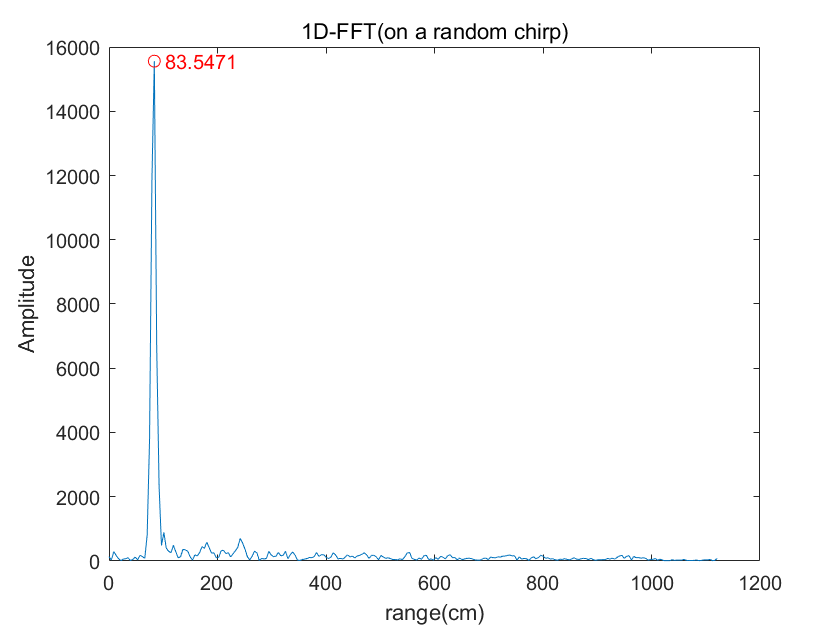

n=chirpLoop/2:chirpLoop:length(Data1filtOut);
IF_mat=Data1filtOut(:,n);
[N,M]=size(IF_mat); %N为每chirp采样点，M为chirp数

%% 生成窗
range_win = hamming(N);  %生成range窗

%% range fft
for i = 1:1:M
    temp = IF_mat(:,i) .* range_win;
    temp_fft = fft(temp,N);
    IF_mat(:,i) = temp_fft;
%     IF_mat(:,i)=temp_fft-mean(temp_fft); %平均相消法滤除杂波
end

%找range-bin
range_bin=(0:N-1)*c*Fs/N/2/k*100; %转换为cm
time=linspace(0,M*Periodicity,M);
[Val,Locs]=max(abs(IF_mat));
[Locs,ord]=mode(Locs); %众数，频次
% range_bin(Locs)

% 某chirp的1D-fft图
for i = 1:1:M
    [a,b]=max(abs(IF_mat(:,i)));
    if b==Locs
       example_chirp=b;
       example_Val=a;
       break
    end
end
figure;
plot(range_bin, abs(IF_mat(:,i))); %abs
text(range_bin(example_chirp),example_Val,['  ',num2str(range_bin(example_chirp))],'Color','red'); %]
hold on
plot(range_bin(example_chirp),example_Val,'ro');
title('1D-FFT(on a random chirp)');
ylabel('Amplitude'); 
xlabel('range(cm)');

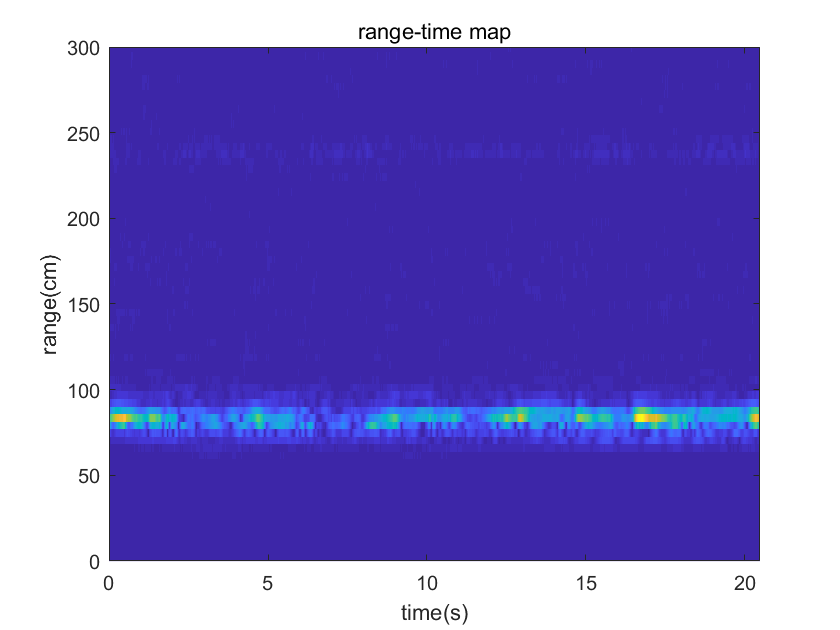


% 时间距离热图
figure;
imagesc(time,range_bin,abs(IF_mat));
set(gca,'YDir','normal') %y轴反向
title('range-time map');
ylabel('range(cm)');
xlabel('time(s)');
ylim([0,300]);

%慢时间采样：Locs代表每个chirp取第Locs个采样点的数据。
n=chirpLoop/2:chirpLoop:length(Data1filtOut);
Data_tmp=Data1filtOut(:,n);
Data_tmp = reshape(Data_tmp(Locs, :), [], 1);
% Data_tmp=Data_tmp(1:1024);
data_num=length(Data_tmp);

% %IQ不平衡补偿
% %求均值
% I_before_correction = real(Data_tmp)-mean(real(Data_tmp));
% Q_before_correction = imag(Data_tmp)-mean(imag(Data_tmp));
% 
% %估计参数
% e = sqrt(mean(Q_before_correction.*Q_before_correction)/mean(I_before_correction.*I_before_correction))-1;
% phi = -asin(mean(I_before_correction.*Q_before_correction)/sqrt(mean(I_before_correction.*I_before_correction)*mean(Q_before_correction.*Q_before_correction)));
% %P矩阵求解
% P = [1,0;tan(phi),1/((1+e)*cos(phi))];
% 
% %计算IQ
% for i=1:length(I_before_correction)
% IQ(:,i) = P*[I_before_correction(i);Q_before_correction(i)];
% end
% %重组信号
% I =IQ(1,:);
% Q =IQ(2,:);
% signal_IQ = I+Q*1j;
% figure();
% pwelch(signal_IQ,  [],[],[],fs);title('Spectrum at Rx baseband after I/Q correction');

% 不考虑IQ不平衡
I =real(Data_tmp);
Q =imag(Data_tmp);
signal_IQ = I+Q*1j;
% %图形绘制
% t=linspace(0,length(I)/fs,length(I));
% plot(t,I)
% % ylim([-2,2])
% title('不平衡补偿后的I');
% plot(t,Q)
% % ylim([-2,2])
% title('不平衡补偿后的Q');

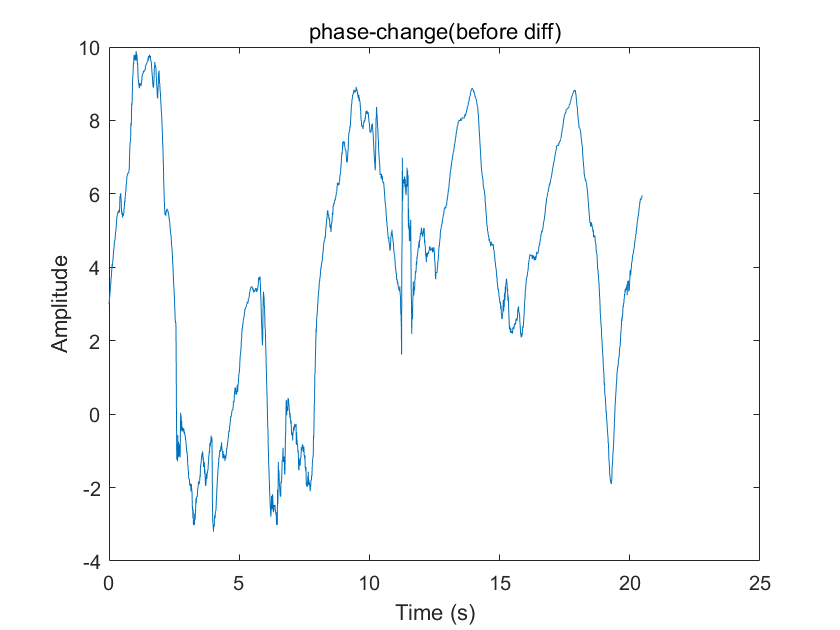

%相位提取和解缠绕
angle_data=angle(signal_IQ);
angle_data=unwrap(angle_data);
%线性去趋势
% angle_data = detrend(angle_data);
% %转置
% angle_data=angle_data'; 
% angle_data=(angle_data-mean(angle_data));
t=linspace(0,data_num*Periodicity,data_num);
figure;
plot(t, angle_data);
xlabel('Time (s)'); 
ylabel('Amplitude'); 
title('phase-change(before diff)');

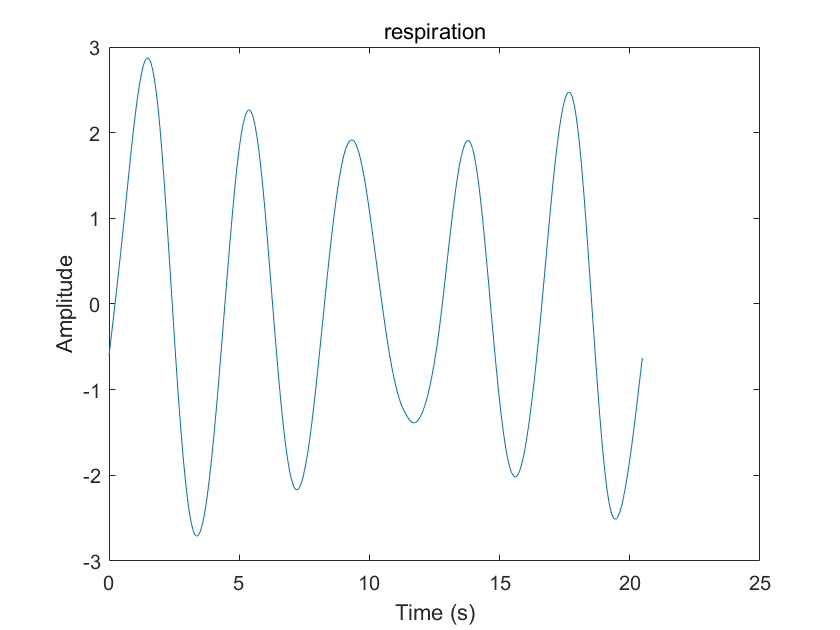

%呼吸信号提取
x = angle_data;
lev=8;
wtecg=modwt(x,'coif1',lev); %coiflet消失矩5，层数为7 coif5
mra=modwtmra(wtecg,'coif1');%MRA
respiration=mra(8,:);
%画图
figure;
plot(t,respiration);
xlabel('Time (s)'); 
ylabel('Amplitude'); 
title('respiration');


%转化为复解析信号（1/2下采样）
%https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=679118
x=respiration';
N=length(x); 
X=fft(x,N); 
z_dec=(1/2)*ifft([(X(1)+X(N/2+1));2*X(2:N/2)],N/2); %长度减半

%MUSIC算法
%https://blog.csdn.net/I_am_mengxinxin/article/details/106046389?ops_request_misc=%257B%2522request%255Fid%2522%253A%2522167774676416800215034888%2522%252C%2522scm%2522%253A%252220140713.130102334..%2522%257D&request_id=167774676416800215034888&biz_id=0&utm_medium=distribute.pc_search_result.none-task-blog-2~all~sobaiduend~default-1-106046389-null-null.142^v73^pc_new_rank,201^v4^add_ask,239^v2^insert_chatgpt&utm_term=%E9%A2%91%E7%8E%87%E4%BC%B0%E8%AE%A1%20music&spm=1018.2226.3001.4187
n=length(z_dec); %信号样本数
s=z_dec;  %估计频率的信号  '
m=8; %自相关矩阵的阶数
for i=1:n-m
    xx(:,i)=s(i+m-1:-1:i).';  %构造样本矩阵
end
R=xx*xx'/(n-m);%自相关矩阵
[EV,D]=eig(R);%特征值分解 
EVA=diag(D)';
[EVA,I]=sort(EVA);%特征值从小到大排序
EVA=fliplr(EVA);%左右翻转，从大到小排序
EV=fliplr(EV(:,I));%对应特征矢量排列
G=EV(:,2:m); %噪声子空间 可以认为只有心跳二次谐波一个分量
NF=2048;

w=linspace(-pi,pi,NF);
for ii=1:NF
    a=exp(-1j*w(ii)*(0:m-1)');% -
    Pmusic(ii)=1/(a'*G*G'*a);
end
Pmusic=abs(Pmusic)/max(abs(Pmusic));

Pmusic=10*log10(Pmusic);
[Val,Locs]=findpeaks(Pmusic,'minpeakheight',-5);
% figure
% for i = 1:1:length(Locs)
%     plot(w(Locs(i))/(2*pi),Val(i),'ro');
%     text(w(Locs(i))/(2*pi),Val(i),num2str(w(Locs(i))/(2*pi)))
%     hold on
% end
% plot(w/(2*pi),Pmusic);
% xlabel('Normalized frequency(Hz)');
% % ylim([-35,5]);
% ylabel('db');
% % title('The frequency of respiration');
% title('The frequency of heartbeat');
heartbeat_fre=w(Locs)/(2*pi)*(fs/2);%/2;
heartbeat_fre=floor(heartbeat_fre*100)/100; %不四舍五入
fprintf ('The Respiratory rate is %.2f Hz',heartbeat_fre);

The Respiratory rate is 0.25 Hz

% fprintf ('The heartbeat frequency is %.2f Hz',heartbeat_fre);

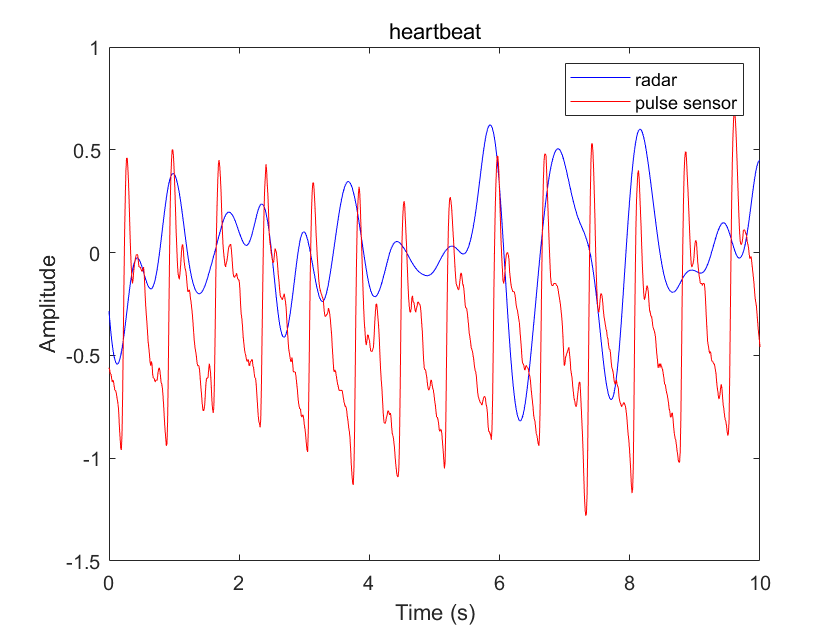

winwide=1024;
Sec_harmonic_heartbeat = zeros(1, data_num);%加窗处理心跳信号
for win = 1:winwide:data_num 
    x=angle_data(win:win+winwide-1);
    %MODWT+MRA
%     x = angle_data;
    % lev=8;
    lev=8;
    wtecg=modwt(x,'coif1',lev); %coiflet消失矩5，层数为7 coif5
    mra=modwtmra(wtecg,'coif1');%MRA
    %各层的能量
    energy_by_level = sum(wtecg.^2,2);
    %加权重构心跳信号
    low_lev=5; % 
    high_lev=6; %假设(1.6-5Hz)与mra第low_lev至high_lev行相对应
    energy_subsum=sum(energy_by_level(low_lev:high_lev));
    
    for i = low_lev:1:high_lev
%         Sec_harmonic_heartbeat(win:win+winwide-1)=mra(i,:);
        Sec_harmonic_heartbeat(win:win+winwide-1)=(energy_by_level(i)/energy_subsum)*mra(i,:);
    end
end

figure;
% plot(t,Sec_harmonic_heartbeat);
% xlim([0,20]);
% xlabel('Time (s)'); 
% ylabel('Amplitude'); 
% title('heartbeat');

%读取csv文件
data=readtable('C:\Users\16242\Desktop\ZHMK-YS\组合模块\CTSensor17.8.15\Data\withreal.csv');
%增加索引列
indexCol=(1:size(data,1)).';
value=table2array(data(:,1));
value=downsample(value,2); %下采样 采样率变为100Hz
%线性去趋势
% value = detrend(value);
%绘制折线图
% figure(6)
% plot(indexCol/200,value);
% xlabel('time');
% ylabel('amp');
% title('data from pulse sensor');
% xlim([140,160]);
% xlim([150,170]);
% plot(t,value(14000:16047));
duiqi=13990;
plot(t,Sec_harmonic_heartbeat,'b-',t,value(duiqi:duiqi+data_num-1)/100-4,'r-');
xlim([0,10]);
xlabel('Time (s)'); 
ylabel('Amplitude'); 
legend('radar','pulse sensor');
title('heartbeat');


% % STFT
% dff=linspace(-50,50,1024);
% [B, F, T, P] = spectrogram(Sec_harmonic_heartbeat,20,19,dff,1/Periodicity);  %采样频率才10Hz
% figure;
% imagesc(T,F,abs(B));
% set(gca,'YDir','normal');
% ylim([-20,20]);
% xlim([0,10]);
% colorbar;
% xlabel('time t/s');
% ylabel('Frequency f/Hz');
% title('STFT');

%转化为复解析信号（1/2下采样）
%https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=679118
x=Sec_harmonic_heartbeat';
N=length(x); 
X=fft(x,N); 
z_dec=(1/2)*ifft([(X(1)+X(N/2+1));2*X(2:N/2)],N/2); %长度减半

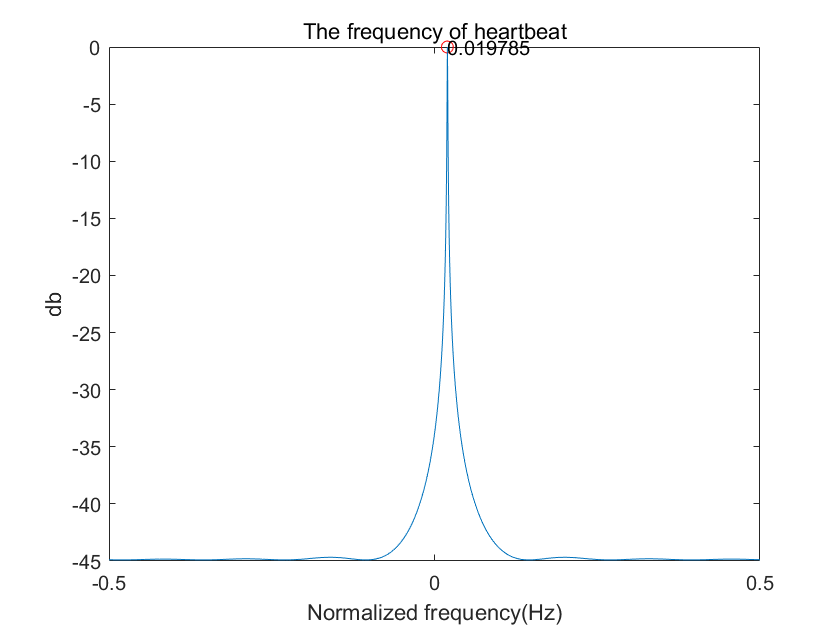

%MUSIC算法
%https://blog.csdn.net/I_am_mengxinxin/article/details/106046389?ops_request_misc=%257B%2522request%255Fid%2522%253A%2522167774676416800215034888%2522%252C%2522scm%2522%253A%252220140713.130102334..%2522%257D&request_id=167774676416800215034888&biz_id=0&utm_medium=distribute.pc_search_result.none-task-blog-2~all~sobaiduend~default-1-106046389-null-null.142^v73^pc_new_rank,201^v4^add_ask,239^v2^insert_chatgpt&utm_term=%E9%A2%91%E7%8E%87%E4%BC%B0%E8%AE%A1%20music&spm=1018.2226.3001.4187
n=length(z_dec); %信号样本数
s=z_dec;  %估计频率的信号  '
m=8; %自相关矩阵的阶数
for i=1:n-m
    xx(:,i)=s(i+m-1:-1:i).';  %构造样本矩阵
end
R=xx*xx'/(n-m);%自相关矩阵
[EV,D]=eig(R);%特征值分解 
EVA=diag(D)';
[EVA,I]=sort(EVA);%特征值从小到大排序
EVA=fliplr(EVA);%左右翻转，从大到小排序
EV=fliplr(EV(:,I));%对应特征矢量排列
G=EV(:,2:m); %噪声子空间 可以认为只有心跳二次谐波一个分量
NF=2048;

w=linspace(-pi,pi,NF);
for ii=1:NF
    a=exp(-1j*w(ii)*(0:m-1)');% -
    Pmusic(ii)=1/(a'*G*G'*a);
end
Pmusic=abs(Pmusic)/max(abs(Pmusic));

Pmusic=10*log10(Pmusic);
[Val,Locs]=findpeaks(Pmusic,'minpeakheight',-5);
figure
for i = 1:1:length(Locs)
    plot(w(Locs(i))/(2*pi),Val(i),'ro');
    text(w(Locs(i))/(2*pi),Val(i),num2str(w(Locs(i))/(2*pi)))
    hold on
end
plot(w/(2*pi),Pmusic);
xlabel('Normalized frequency(Hz)');
% ylim([-35,5]);
ylabel('db');
% title('The frequency of respiration');
title('The frequency of heartbeat');

The heartbeat frequency is 0.98 Hz

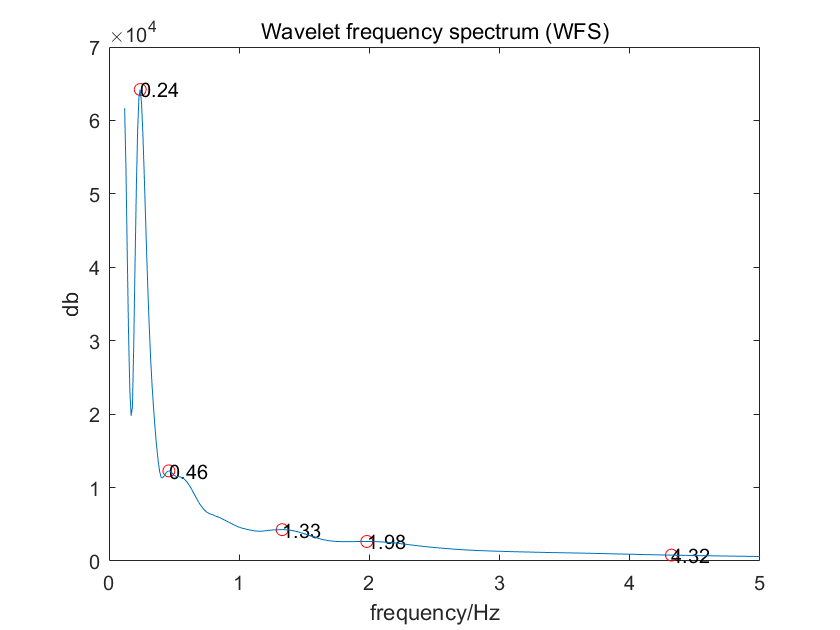

heartbeat_fre=w(Locs)/(2*pi)*(fs/2);%/2;
heartbeat_fre=floor(heartbeat_fre*100)/100; %不四舍五入
% fprintf ('The Respiratory rate is %.2f Hz',heartbeat_fre);
fprintf ('The heartbeat frequency is %.2f Hz',heartbeat_fre);